# **IO133 - DMA Loopback**

This example demonstrates how the first two inputs and outputs present on the IO133 I/O module communicate using DMA (Direct Memory Access). The model is triggered by the IO133's DMA interrupt.

The IO133 is a fast, simultaneous-sampling, 16-bit analog input and output module, complete with dedicated Simulink® driver blocks.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO133 I/O module installed

- Connector cable from the I/O module to the terminal board

- 68-pin terminal board with jumper wires

### Test Setup

On the terminal board of the analog I/O module, connect the positive (+) pins of Analog Inputs 1 and 2 to the pins of Analog Outputs 1 and 2, and connect the negative (-) pins of Analog Inputs 1 and 2 to GND. Finally, connect DIO 1 and DIO 5.

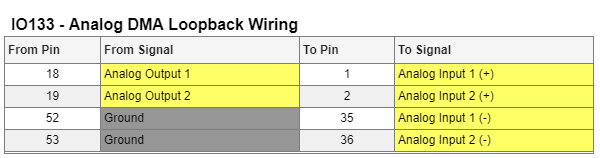

[IO133 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io133_pin_mapping)

## Initialize and Open the Simulink model

 
% Open Simulink model
modelName = 'sgMdl_IO133_DMALoopback';
open_system(modelName);

### Model Description

The Simulink model features the [IO133 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io133_setup_v2), [IO133 Analog Input](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io133_analog_input_v2), [IO133 Analog Output](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io133_analog_output_v2), [IO133 Digital Input](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io133_digital_input_v2) and [IO133 Digital Output](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io133_digital_output_v2) blocks. Analog Inputs and Outputs 1 and 2, as well as Digital Inputs and Outputs 1 and 5 are enabled in the [IO133 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io133_setup_v2) block. Furthermore, the model features a [Speedgoat Interrupt Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_interrupt_setup) block, configured as model trigger. If you wish to reuse the example in a larger Simulink model, consider putting the blocks into a function-triggered subsystem and configuring the Interrupt Setup block accordingly.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;            
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName); 

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode',   'external')   % put model into External Mode
set_param(modelName,'SimulationCommand','connect')    % connect with External Mode   

% Start the real-time application
tg.setStopTime(10);
tg.start;

% The real-time application on the target machine will automatically stop after 10 seconds

### Check the Results

By clicking on the scope after the model has terminated, you should be able to see the input signals of both channels.

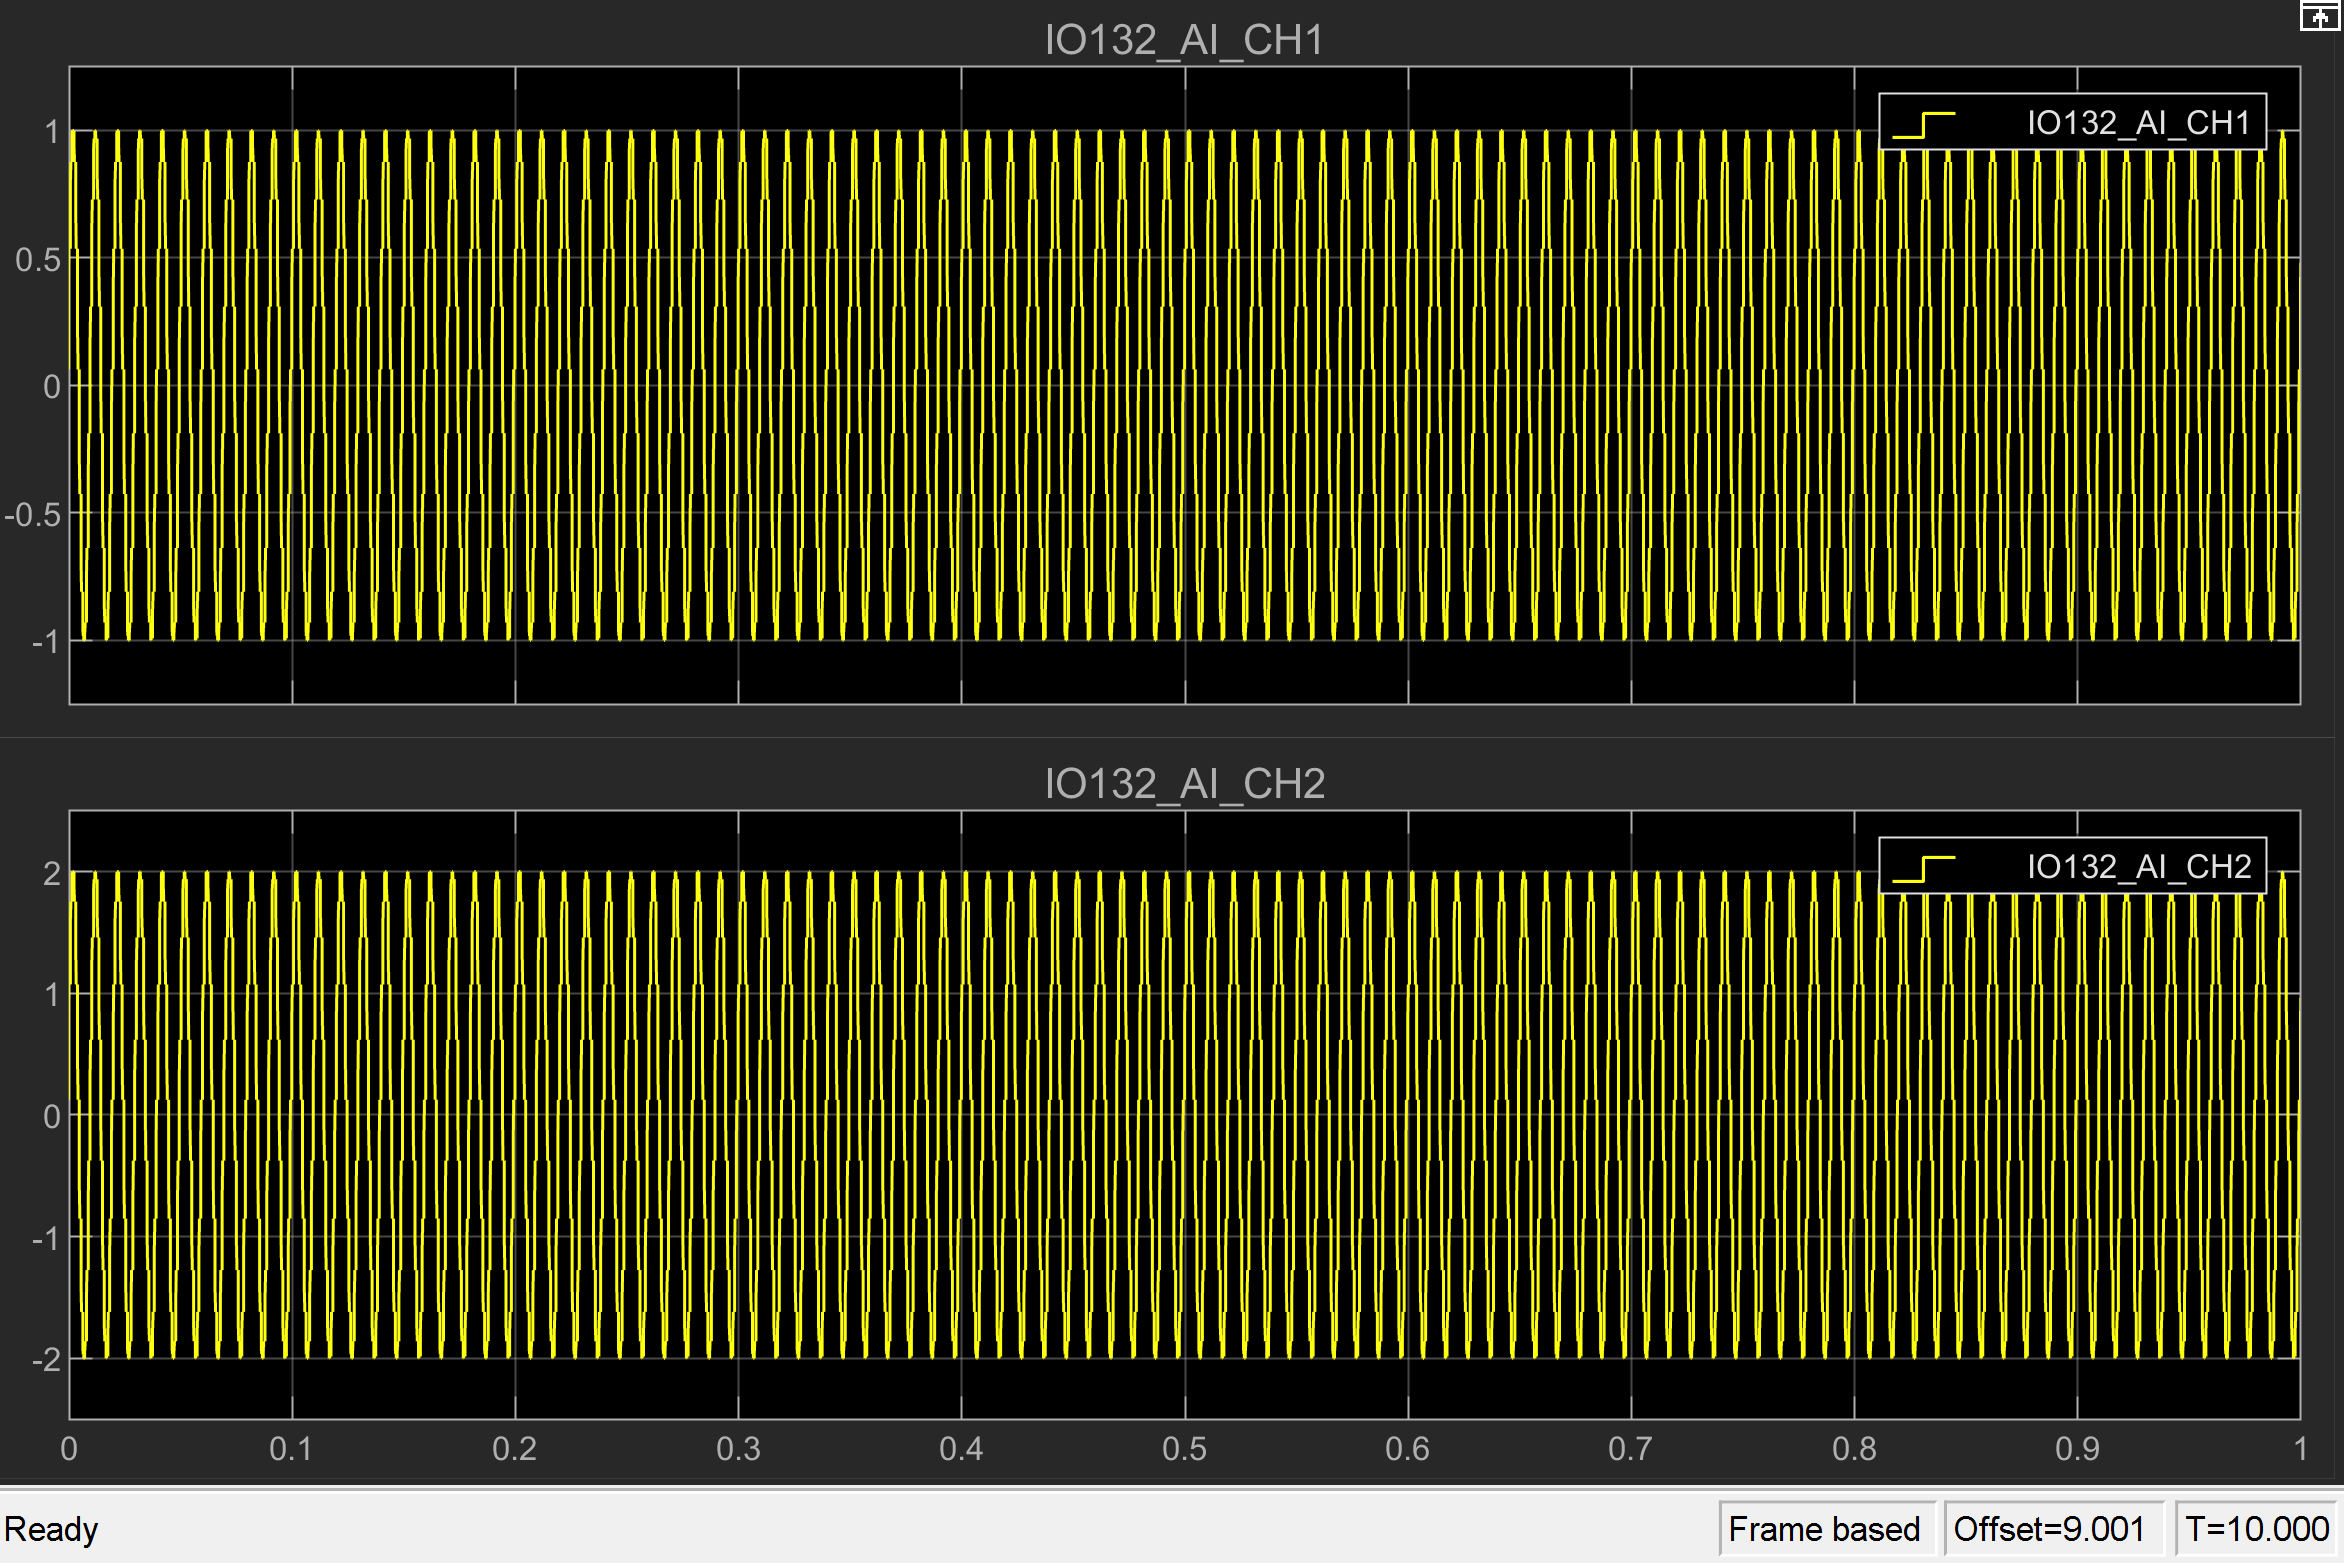

If you zoom in horizontally, you can see the increased sample rate thanks to the active DMA on the module.

Ensure that in the scope, under **View > Configuration Properties > Main**, the **Input Processing** option is set to **Columns as channels (frame based)**.

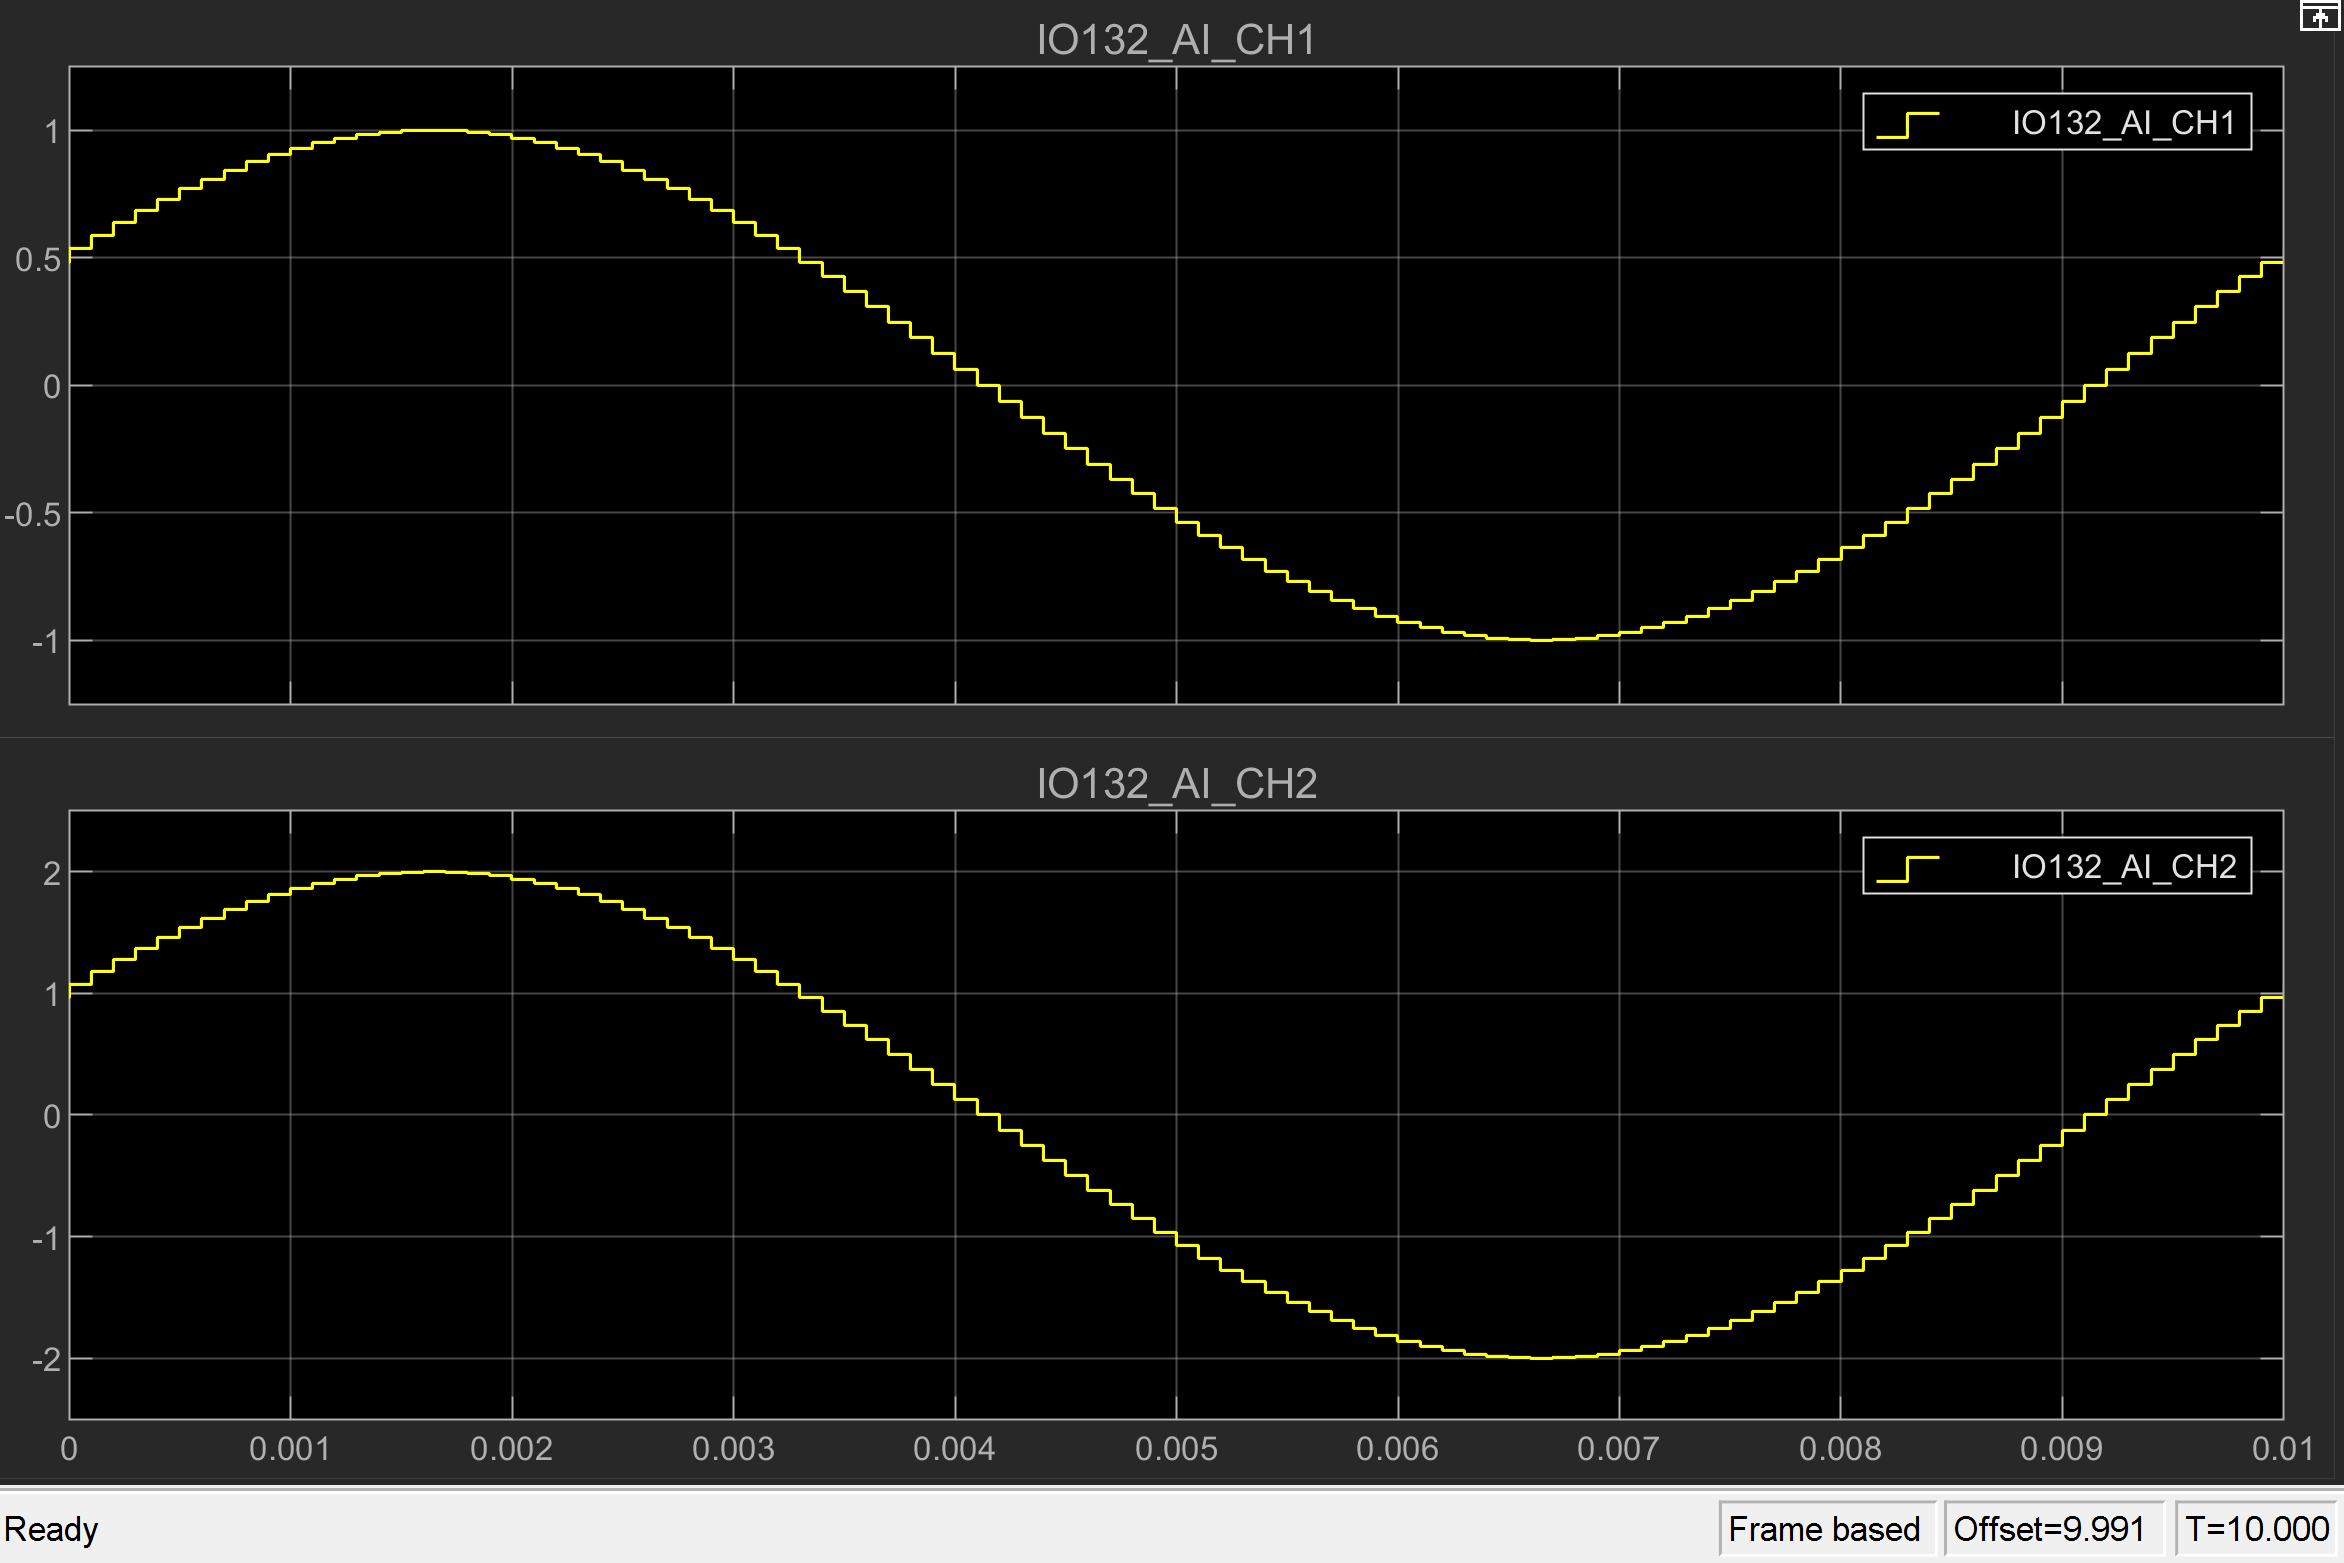

## Additional References

- [IO133 examples and documentation](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io133)

- [DSP System Toolbox: Sample- and Frame-Based Concepts](https://mathworks.com/help/dsp/ug/sample-and-frame-based-concepts.html)